filename = 'soda-lime'

filename = 'soda-lime'

data = readmatrix([filename,'.xlsx']);
lambda_n = data(:,1);
n = data(:,2);
lambda_k = data(:,3);
k = data(:,4);

lambda_n = lambda_n(~isnan(lambda_n));
n = n(~isnan(lambda_n));
lambda_k = lambda_k(~isnan(lambda_k));
k = k(~isnan(lambda_k));

lambda1 = max([lambda_n(1),lambda_k(1),0.1]);
lambda2 = min([lambda_n(end),lambda_k(end),5]);
lambda = linspace(lambda1,lambda2,length(lambda_n));

n_intp = interp1(lambda_n,n,lambda,"cubic");

k_intp = interp1(lambda_k,k,lambda,"cubic");

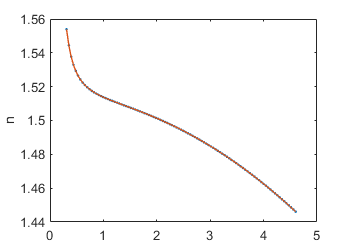


figure('Position',[0 0 350 250])
plot(lambda_n,n,'.','LineWidth',1.5);
hold on
plot(lambda,n_intp,'-','LineWidth',1);
ylabel('n')

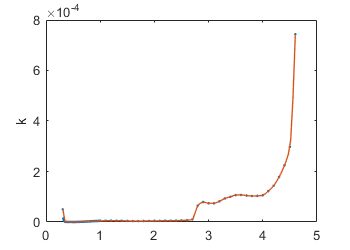

figure('Position',[0 0 350 250])
plot(lambda_k,k,'.','LineWidth',1.5);
hold on
plot(lambda,k_intp,'-','LineWidth',1);
ylabel('k')


data = [lambda(:),n_intp(:),k_intp(:)];
writematrix(data,[filename,'.txt'])